# Modelling - Decision Tree & K-Nearest Neighbor

## 1) Setup

Clear workspace, load datasets with different preprocessings and convert to matrices

clear; clc; % Clear workspace
rng(1) % set seed for reproducability

% Load baseline train and test data
train = readtable('train.csv', 'ReadVariableNames', true);
test = readtable('test.csv', 'ReadVariableNames', true);

feature_names = train.Properties.VariableNames(2:end);

train = train{:,:};  % Convert to matrix
test = test{:,:};

X_train = train(:, 2:end); % Split into target and features 
y_train = train(:, 1);
X_test = test(:, 2:end);
y_test = test(:, 1);

% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

## 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy)

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 10);

% DECISION TREE: Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
ParamsDT = [MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
n = optimizableVariable('n',[1,16],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
ParamsKNN = [n; dst];

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014878 |     0.43282 |    0.014878 |    0.014878 |           22 |            3 |
|    2 | Best   |    0.014759 |     0.25302 |    0.014759 |    0.014759 |            3 |           30 |
|    3 | Accept |    0.014819 |     0.32266 |    0.014759 |    0.014759 |            6 |            2 |
|    4 | Accept |    0.014759 |     0.42483 |    0.014759 |    0.014759 |           12 |           29 |
|    5 | Accept |    0.014819 |     0.53114 |    0.014759 |    0.014759 |           29 |           14 |
|    6 | Accept |    0.014759 |     0.40299 |    0.014759 |    0

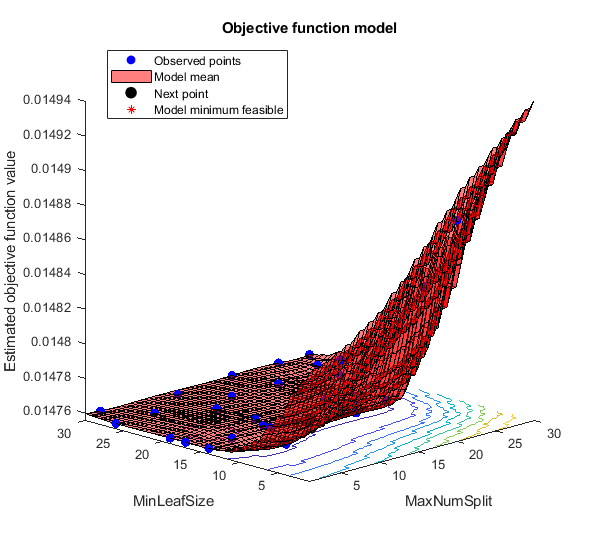

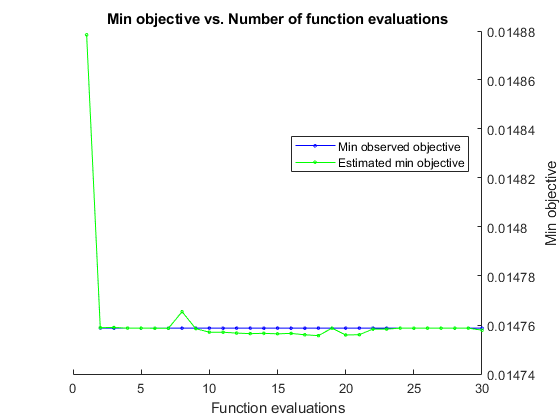


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 25.4591 seconds
Total objective function evaluation time: 10.5115

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         3             30     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.25302

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        21             15     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.39113



% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

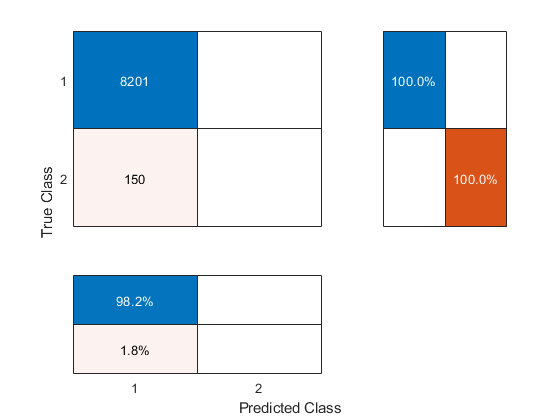

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

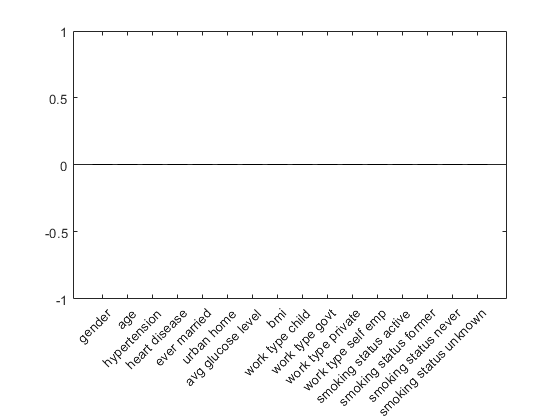

% Show feature importance
imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014908 |      4.5698 |    0.014908 |    0.014908 |            6 |    euclidean |
|    2 | Best   |    0.014759 |      4.3641 |    0.014759 |    0.014833 |           10 |       cosine |
|    3 | Accept |    0.014759 |      4.5797 |    0.014759 |    0.014759 |           15 |    euclidean |
|    4 | Accept |    0.025626 |      4.3888 |    0.014759 |    0.014974 |            2 |       cosine |
|    5 | Accept |    0.014759 |      4.5463 |    0.014759 |    0.014759 |           12 |    euclidean |
|    6 | Accept |    0.014759 |      4.3921 |    0.014759 |    0

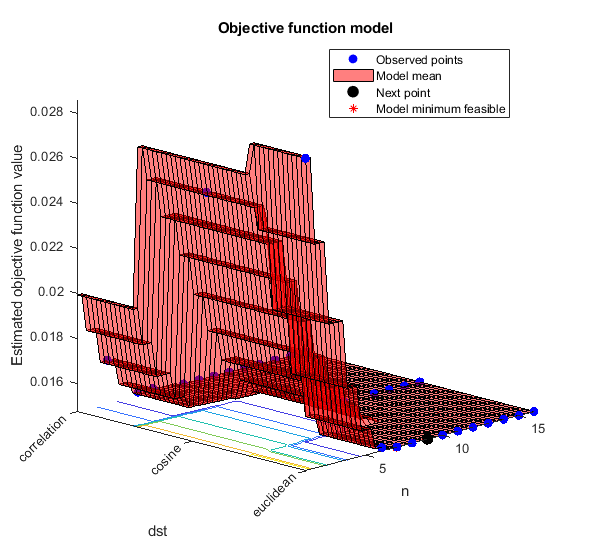

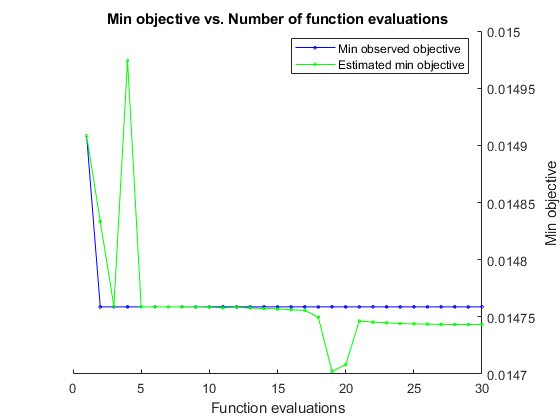


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 151.3557 seconds
Total objective function evaluation time: 134.8549

Best observed feasible point:
    n      dst  
    __    ______

    10    cosine

Observed objective function value = 0.014759
Estimated objective function value = 0.014762
Function evaluation time = 4.3641

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    7    euclidean

Estimated objective function value = 0.014743
Estimated function evaluation time = 4.5698



% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.23736 |           1 |           1 |            2 |           23 |
|    2 | Accept |           1 |     0.38721 |           1 |           1 |           28 |           11 |
|    3 | Accept |           1 |     0.36786 |           1 |           1 |            7 |           21 |
|    4 | Best   |     0.99747 |     0.40492 |     0.99747 |     0.99747 |           21 |            3 |
|    5 | Accept |           1 |     0.41676 |     0.99747 |     0.99747 |           25 |           24 |
|    6 | Best   |     0.99747 |     0.35892 |     0.99747 |     

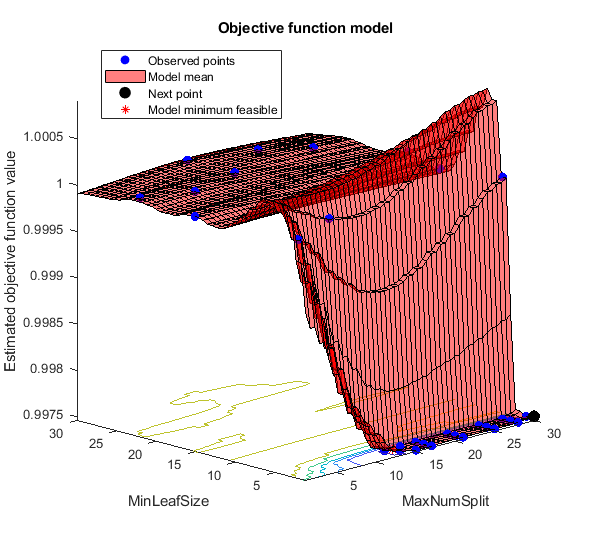

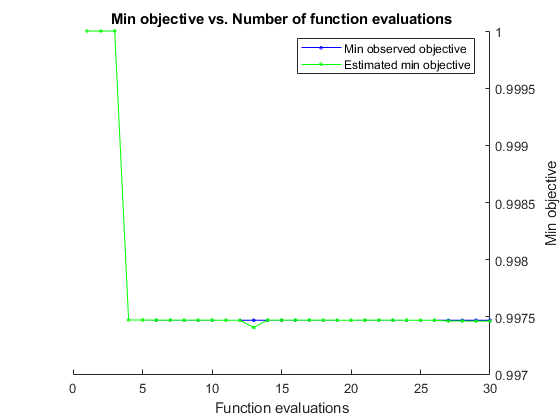


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 30.7226 seconds
Total objective function evaluation time: 12.7921

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        13              3     

Observed objective function value = 0.99747
Estimated objective function value = 0.99748
Function evaluation time = 0.35892

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        15              3     

Estimated objective function value = 0.99746
Estimated function evaluation time = 0.42963



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

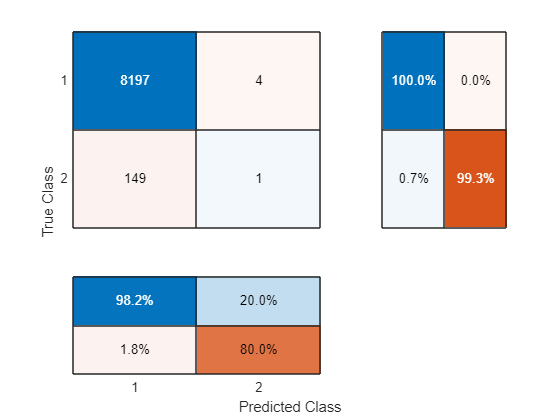

accuracy = 0.9817

precision = 0.2000

recall = 0.0067

specificity = 0.9995

fb = 0.0083


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

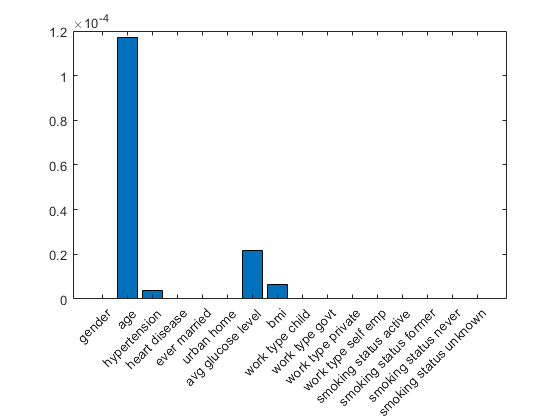

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.96968 |      5.6674 |     0.96968 |     0.96968 |            1 |       cosine |
|    2 | Accept |           1 |      5.2099 |     0.96968 |     0.97125 |           15 |       cosine |
|    3 | Accept |     0.99752 |      4.5488 |     0.96968 |     0.98041 |            4 |       cosine |
|    4 | Accept |           1 |      5.1949 |     0.96968 |     0.98013 |           11 |    euclidean |
|    5 | Accept |           1 |      4.4135 |     0.96968 |     0.97152 |           14 |  correlation |
|    6 | Accept |           1 |      4.4879 |     0.96968 |     

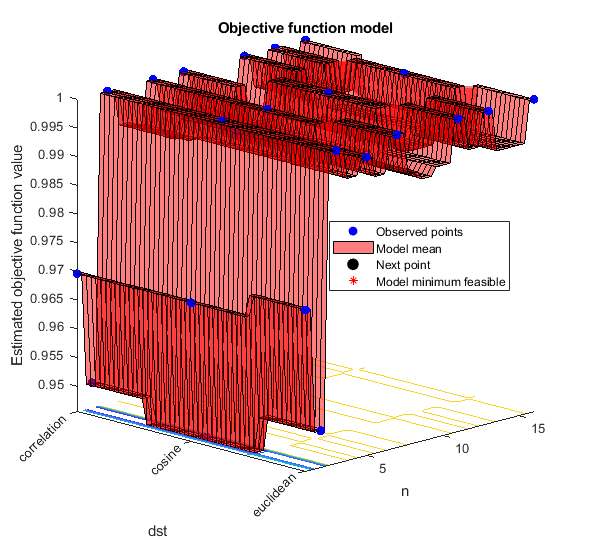

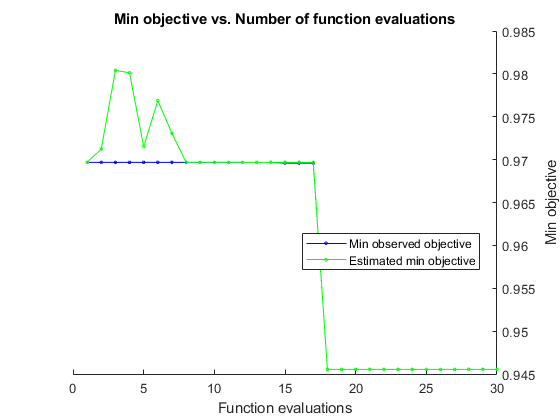


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 159.3107 seconds
Total objective function evaluation time: 139.5102

Best observed feasible point:
    n     dst  
    _    ______

    2    cosine

Observed objective function value = 0.94554
Estimated objective function value = 0.94554
Function evaluation time = 4.3357

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    2    cosine

Estimated objective function value = 0.94554
Estimated function evaluation time = 4.6358



% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

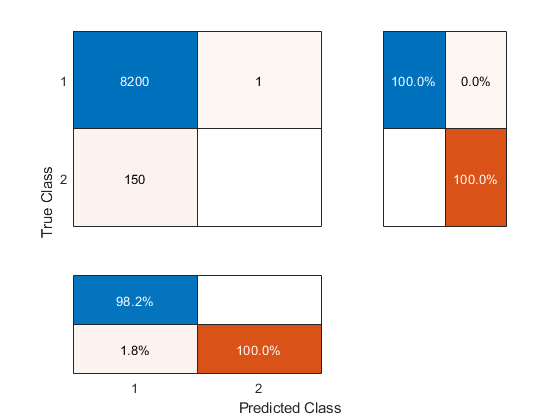

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 4) Hyperparameter Tuning Models (CV = stratify, loss = accuracy)

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 10, 'Stratify', true);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014789 |     0.37849 |    0.014789 |    0.014789 |            6 |            2 |
|    2 | Best   |    0.014759 |     0.47202 |    0.014759 |     0.01476 |            8 |           18 |
|    3 | Accept |    0.014759 |     0.41087 |    0.014759 |    0.014759 |           22 |           23 |
|    4 | Accept |    0.014759 |     0.36017 |    0.014759 |    0.014758 |           14 |           19 |
|    5 | Accept |    0.014759 |     0.36553 |    0.014759 |    0.014759 |           17 |           27 |
|    6 | Accept |    0.014849 |      0.4147 |    0.014759 |    0

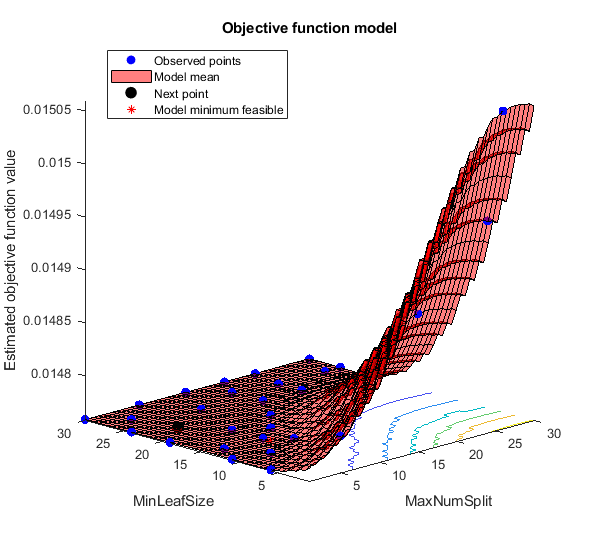

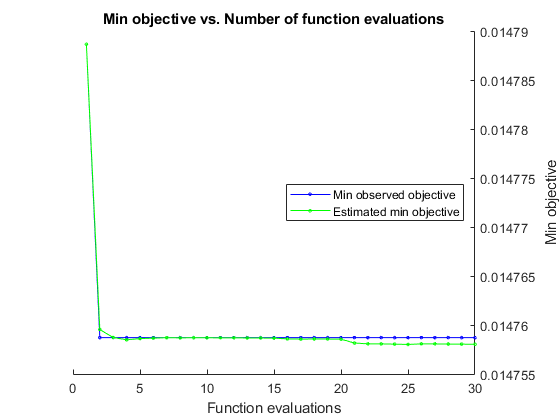


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 29.4883 seconds
Total objective function evaluation time: 10.3639

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         8             18     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.47202

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         8             14     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.36495



% 4a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 4a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c_strat, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

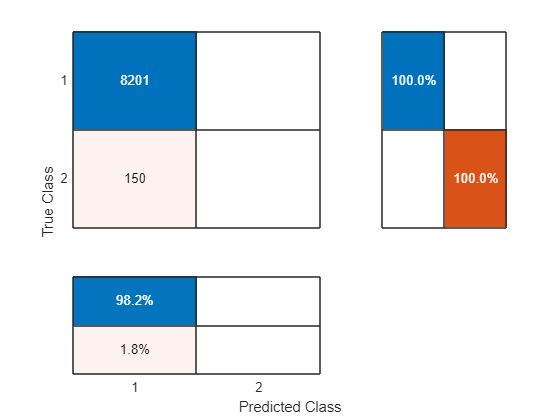

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014759 |      4.4607 |    0.014759 |    0.014759 |           15 |  correlation |
|    2 | Accept |    0.014759 |      4.6395 |    0.014759 |    0.014759 |           12 |    euclidean |
|    3 | Accept |    0.014759 |      4.6665 |    0.014759 |    0.014759 |           13 |       cosine |
|    4 | Accept |    0.023291 |      4.3553 |    0.014759 |     0.01476 |            2 |       cosine |
|    5 | Accept |    0.014759 |      4.6493 |    0.014759 |    0.014759 |           14 |    euclidean |
|    6 | Accept |    0.014998 |      4.5178 |    0.014759 |    0

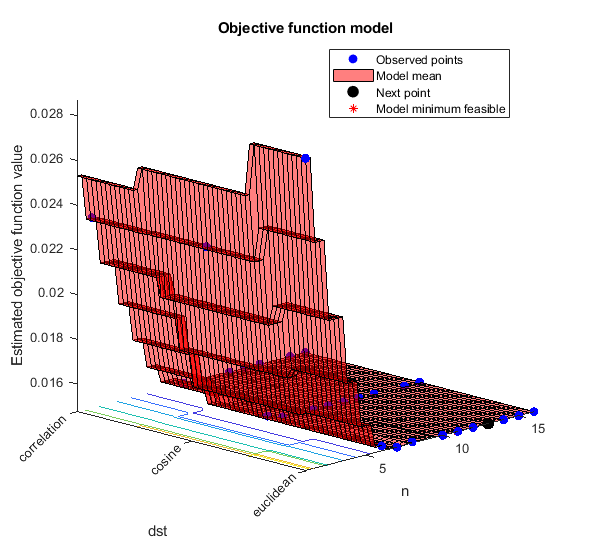

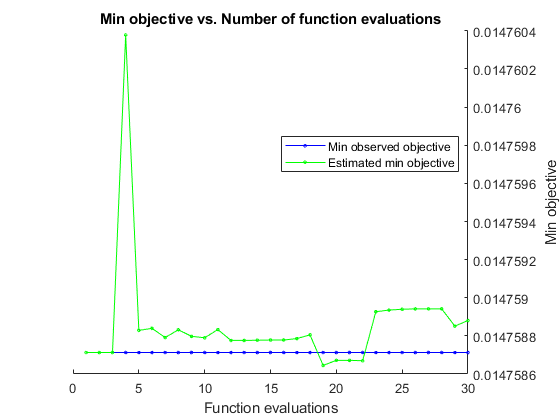


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 167.4293 seconds
Total objective function evaluation time: 145.9391

Best observed feasible point:
    n         dst    
    __    ___________

    15    correlation

Observed objective function value = 0.014759
Estimated objective function value = 0.014758
Function evaluation time = 4.4607

Best estimated feasible point (according to models):
    n      dst  
    __    ______

    13    cosine

Estimated objective function value = 0.014759
Estimated function evaluation time = 4.8492



% 4b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 4b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c_strat, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 5) Hyperparameter Tuning Models (CV = statify, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.57567 |           1 |           1 |           30 |           23 |
|    2 | Accept |           1 |     0.26482 |           1 |           1 |            2 |            8 |
|    3 | Best   |     0.99495 |     0.59218 |     0.99495 |     0.99827 |           29 |            9 |
|    4 | Accept |           1 |     0.60564 |     0.99495 |     0.99871 |           18 |           30 |
|    5 | Accept |           1 |     0.40121 |     0.99495 |     0.99899 |           24 |            3 |
|    6 | Accept |           1 |     0.22288 |     0.99495 |     

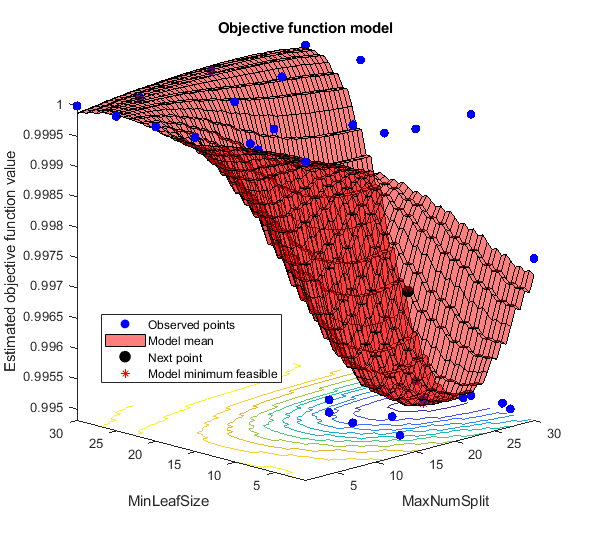

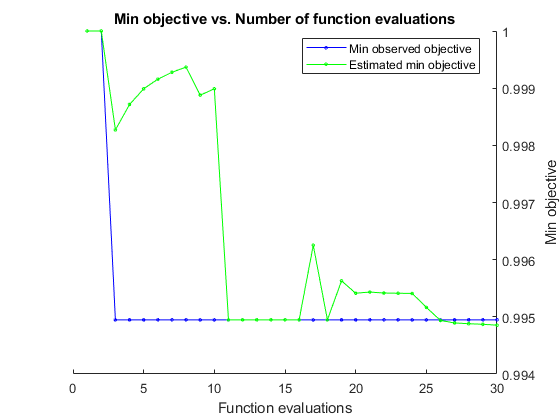


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 33.449 seconds
Total objective function evaluation time: 11.6704

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              9     

Observed objective function value = 0.99495
Estimated objective function value = 0.99502
Function evaluation time = 0.59218

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26             11     

Estimated objective function value = 0.99485
Estimated function evaluation time = 0.45216



% 5a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 5a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.98765 |      4.4227 |     0.98765 |     0.98765 |            3 |       cosine |
|    2 | Best   |     0.95766 |      4.5847 |     0.95766 |     0.97265 |            1 |  correlation |
|    3 | Accept |           1 |       5.035 |     0.95766 |     0.98163 |           13 |    euclidean |
|    4 | Accept |           1 |      4.6336 |     0.95766 |      0.9597 |           15 |  correlation |
|    5 | Accept |           1 |      4.9576 |     0.95766 |     0.95767 |            9 |  correlation |
|    6 | Accept |           1 |      4.7221 |     0.95766 |     

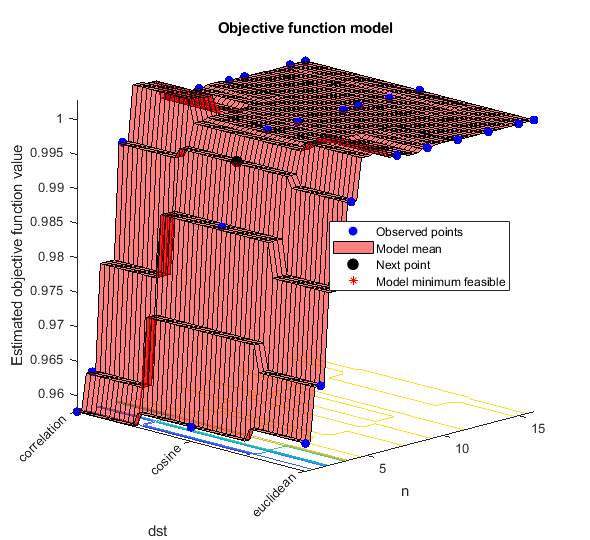

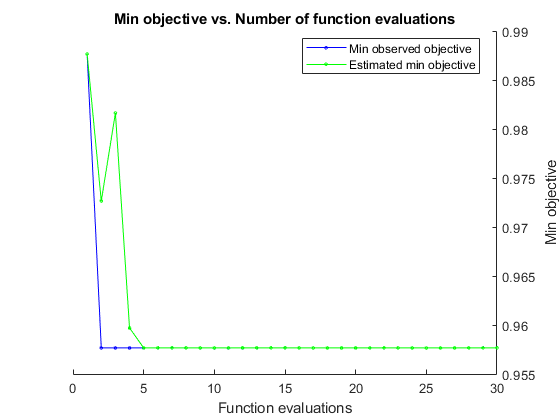


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 170.7717 seconds
Total objective function evaluation time: 146.3992

Best observed feasible point:
    n        dst    
    _    ___________

    1    correlation

Observed objective function value = 0.95766
Estimated objective function value = 0.95766
Function evaluation time = 4.5847

Best estimated feasible point (according to models):
    n        dst    
    _    ___________

    1    correlation

Estimated objective function value = 0.95766
Estimated function evaluation time = 4.8621



% 5b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat); % see helper function

% 5b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

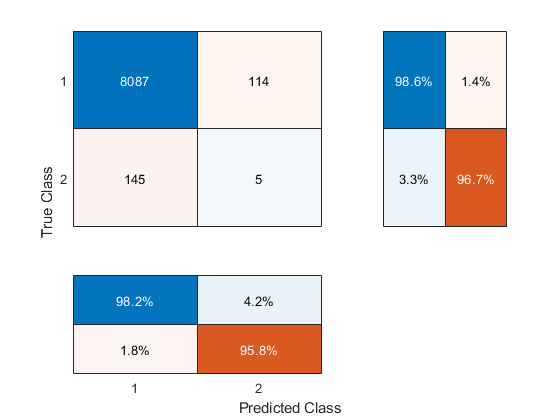

accuracy = 0.9690

precision = 0.0420

recall = 0.0333

specificity = 0.9861

fb = 0.0348


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE)

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 10);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.092021 |      1.2689 |    0.092021 |    0.092021 |           19 |           16 |
|    2 | Best   |    0.089651 |     0.95683 |    0.089651 |    0.090836 |           28 |           23 |
|    3 | Accept |    0.091064 |     0.97921 |    0.089651 |    0.089936 |           20 |            9 |
|    4 | Accept |     0.10644 |     0.83711 |    0.089651 |    0.089651 |           14 |            8 |
|    5 | Accept |    0.089712 |     0.90593 |    0.089651 |    0.089651 |           23 |            3 |
|    6 | Accept |     0.13889 |     0.70429 |    0.089651 |    0

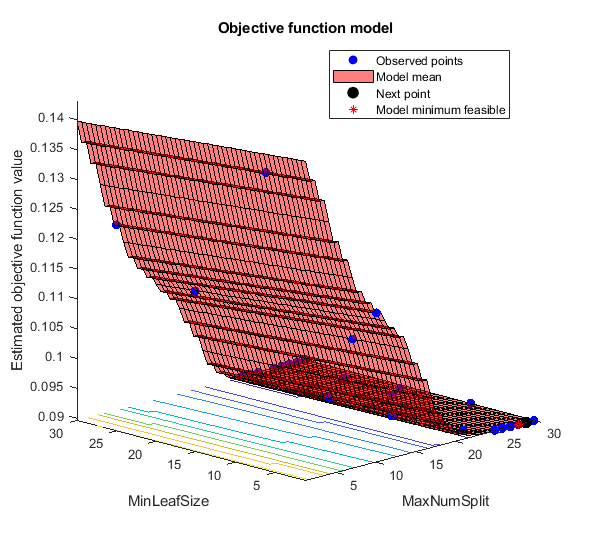

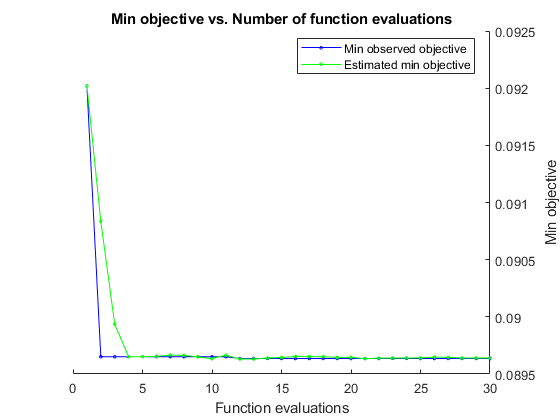


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 53.4821 seconds
Total objective function evaluation time: 27.1718

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        28              1     

Observed objective function value = 0.089636
Estimated objective function value = 0.08964
Function evaluation time = 0.94588

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        28              1     

Estimated objective function value = 0.08964
Estimated function evaluation time = 0.90492



% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

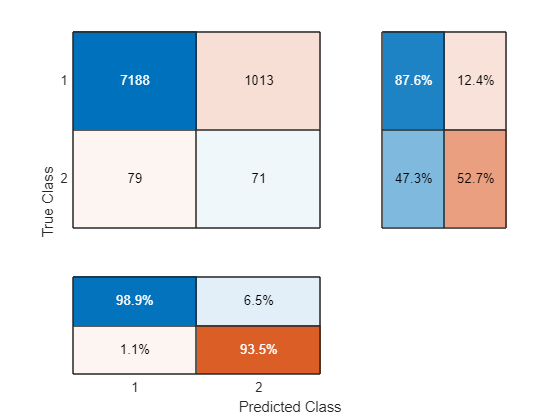

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.2108

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

save('dt_best.mat','dt_best')  % Save best model

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

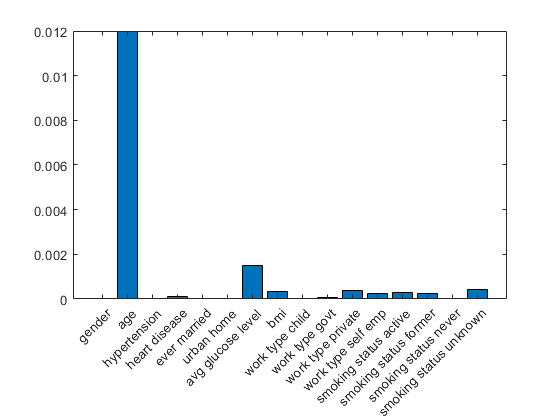

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.017897 |      20.476 |    0.017897 |    0.017897 |           13 |    euclidean |
|    2 | Best   |    0.012063 |      18.535 |    0.012063 |    0.012429 |            3 |  correlation |
|    3 | Accept |    0.015162 |      18.161 |    0.012063 |    0.014005 |            1 |       cosine |
|    4 | Accept |    0.015648 |      18.153 |    0.012063 |    0.015167 |            9 |  correlation |
|    5 | Accept |    0.014372 |      19.331 |    0.012063 |    0.015019 |            7 |    euclidean |
|    6 | Accept |    0.018033 |      17.859 |    0.012063 |    0

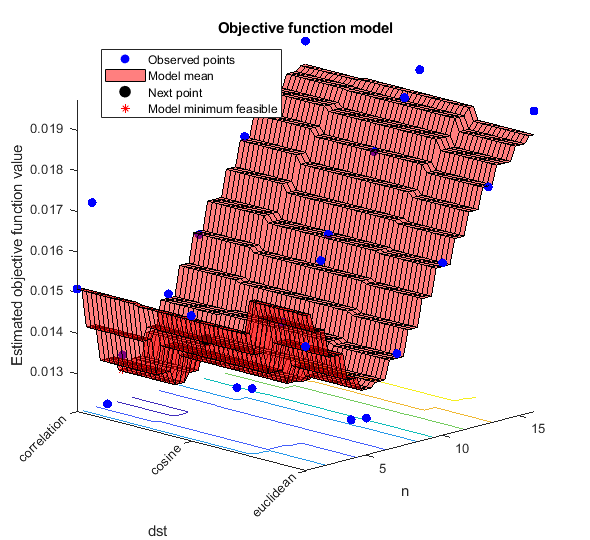

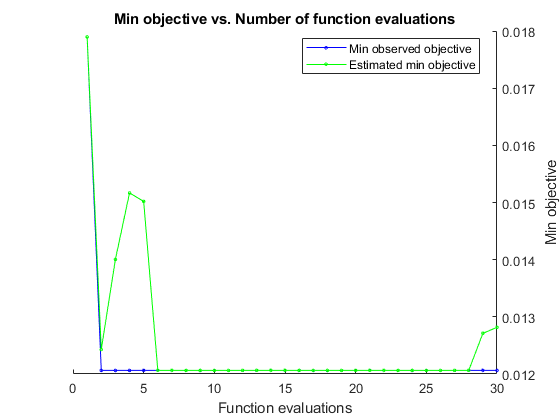


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 598.6269 seconds
Total objective function evaluation time: 555.5528

Best observed feasible point:
    n        dst    
    _    ___________

    3    correlation

Observed objective function value = 0.012063
Estimated objective function value = 0.01318
Function evaluation time = 18.5353

Best estimated feasible point (according to models):
    n        dst    
    _    ___________

    4    correlation

Estimated objective function value = 0.012816
Estimated function evaluation time = 18.4105



% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

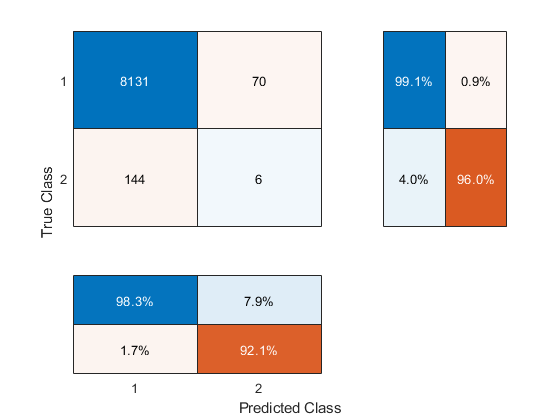

accuracy = 0.9744

precision = 0.0789

recall = 0.0400

specificity = 0.9915

fb = 0.0444

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

save('knn_best.mat','knn_best')  % Save best model

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 7) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.090343 |     0.50199 |    0.090343 |    0.090343 |            2 |           23 |
|    2 | Best   |    0.065228 |     0.87123 |    0.065228 |    0.066479 |           28 |           11 |
|    3 | Accept |    0.087802 |     0.67475 |    0.065228 |    0.065231 |            7 |           21 |
|    4 | Accept |    0.068324 |       1.081 |    0.065228 |    0.065228 |           21 |            3 |
|    5 | Accept |    0.065271 |     0.99016 |    0.065228 |    0.065219 |           25 |           24 |
|    6 | Accept |    0.073885 |      0.7731 |    0.065228 |    0

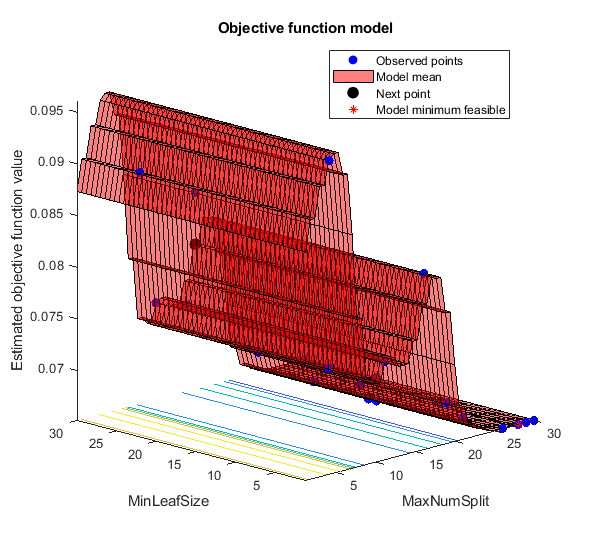

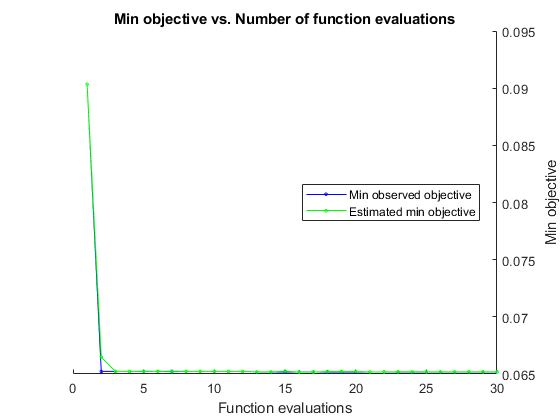


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 50.9552 seconds
Total objective function evaluation time: 26.7241

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.06518
Estimated objective function value = 0.065231
Function evaluation time = 1.0388

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        28              1     

Estimated objective function value = 0.065188
Estimated function evaluation time = 0.94523



% 7a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 7a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 7a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.2108


% 7a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 7a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.013691 |      19.104 |    0.013691 |    0.013691 |            1 |       cosine |
|    2 | Accept |    0.014854 |      19.326 |    0.013691 |    0.014216 |           15 |       cosine |
|    3 | Best   |    0.012716 |      23.635 |    0.012716 |    0.012717 |            4 |       cosine |
|    4 | Accept |    0.014268 |      20.073 |    0.012716 |    0.012717 |           11 |    euclidean |
|    5 | Accept |    0.014742 |      18.286 |    0.012716 |    0.012717 |           14 |  correlation |
|    6 | Accept |    0.013344 |      19.732 |    0.012716 |    0

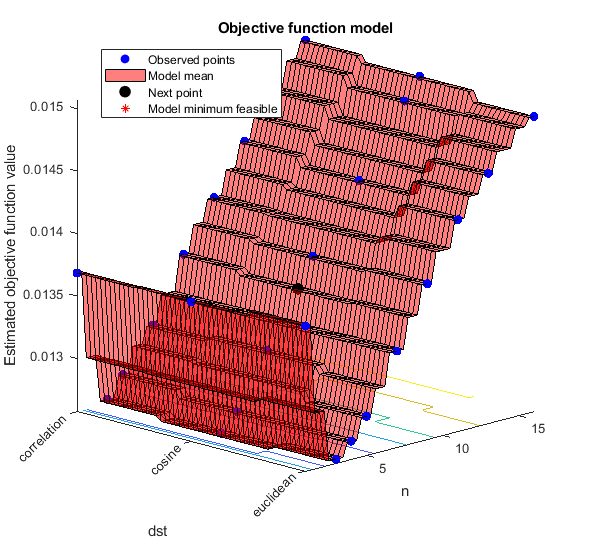

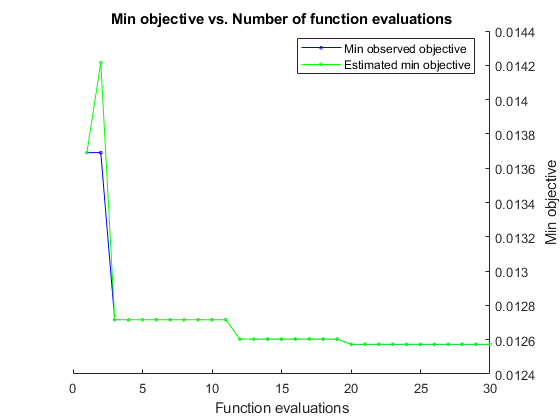


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 646.0137 seconds
Total objective function evaluation time: 617.8868

Best observed feasible point:
    n     dst  
    _    ______

    3    cosine

Observed objective function value = 0.012573
Estimated objective function value = 0.012573
Function evaluation time = 18.1195

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    3    cosine

Estimated objective function value = 0.012573
Estimated function evaluation time = 20.1015



% 7b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 7b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 7b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

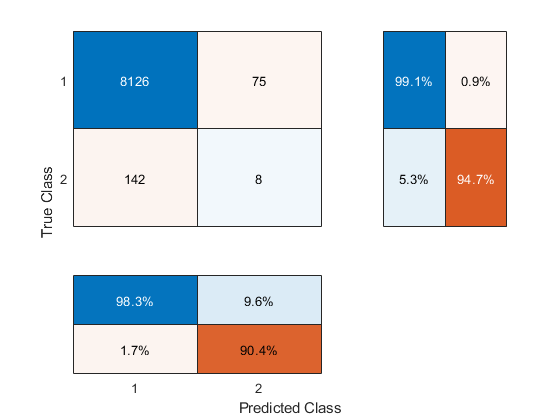

accuracy = 0.9740

precision = 0.0964

recall = 0.0533

specificity = 0.9909

fb = 0.0586


% 7b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 7b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);  % Predict with test data
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);  % Plot confusion matrix
    cm.RowSummary = 'row-normalized';  % Add row summary
    cm.ColumnSummary = 'column-normalized';  % Add column summary
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) % Calculate metrics
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);

        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', cv_part, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);  % Get confusion matrix
    tn = cmat(1,1);  % True negative
    fn = cmat(2,1);  % False negative
    tp = cmat(2,2);  % True positive
    fp = cmat(1,2);  % False positive

    % Statistics of interest for confusion matrix
    b = 2; % beta < 1 favors precision. beta > 1 favors recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp); % accuracy
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2*fn + fp); % F-beta score (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 